# HW 3 - matlab code 

## problem 1 

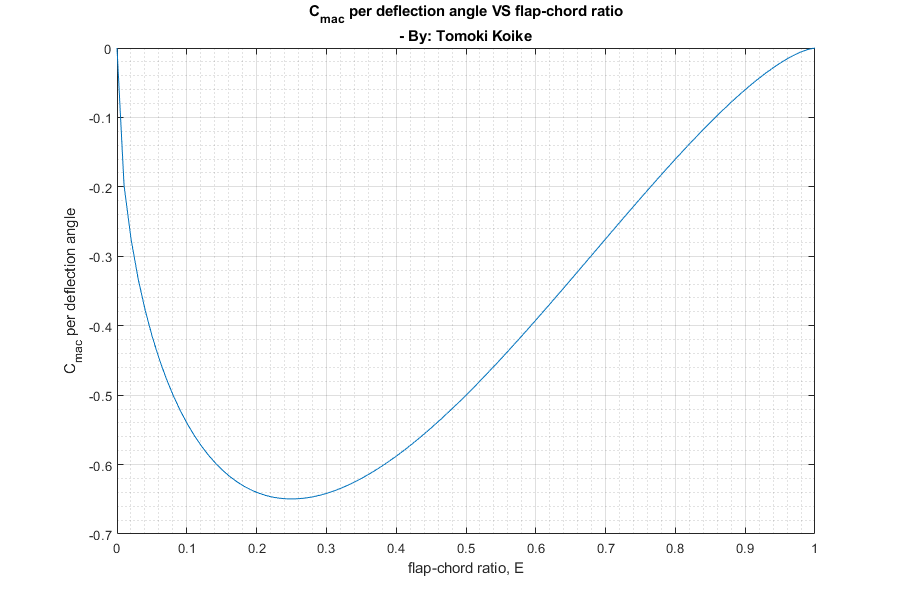

clear all; close all; clc

% Plotting the moment coefficient about the aerodynamic center
E = linspace(0,1,100);  % flap-chord ratio 
C_mac_over_deflect = -2*(1-E).*sqrt(E.*(1-E));  % coefficient per deflection angle
fig1 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(E, C_mac_over_deflect)
xlabel('flap-chord ratio, E')
ylabel('C_m_a_c per deflection angle')
title({'C_m_a_c per deflection angle VS flap-chord ratio', ...
    '- By: Tomoki Koike'})
grid on 
grid minor 
box on 
saveas(fig1, 'mmt_coeff.png')

## problem 2

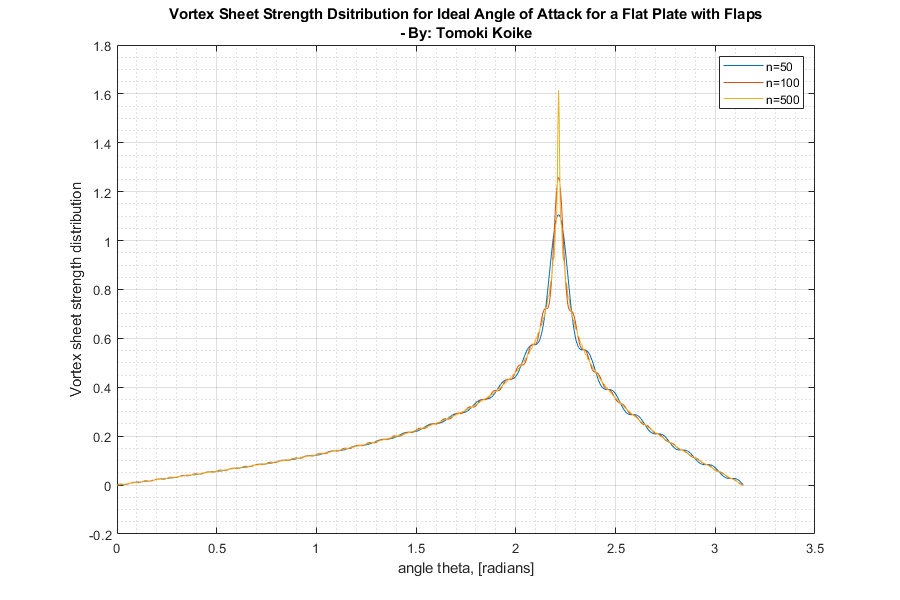

theta = linspace(0, pi, 2^10);  % Define the angle theta 
gamma_over_Vinf_50 = 0;  % Initiate vortex sheet strength distribution 
for n = 1:50
    A_n = sin(n*acos(-0.6)).*sin(n.*theta)/n;  % n-th Fourier coefficient 
    gamma_over_Vinf_50 = gamma_over_Vinf_50 + A_n;  % Summation 
end
gamma_over_Vinf_50 = 4/9 * gamma_over_Vinf_50;

gamma_over_Vinf_100 = 0;  % Initiate vortex sheet strength distribution 
for n = 1:100
    A_n = sin(n*acos(-0.6)).*sin(n.*theta)/n;  % n-th Fourier coefficient 
    gamma_over_Vinf_100 = gamma_over_Vinf_100 + A_n;  % Summation 
end
gamma_over_Vinf_100 = 4/9 * gamma_over_Vinf_100;

gamma_over_Vinf_500 = 0;  % Initiate vortex sheet strength distribution 
for n = 1:500
    A_n = sin(n*acos(-0.6)).*sin(n.*theta)/n;  % n-th Fourier coefficient 
    gamma_over_Vinf_500 = gamma_over_Vinf_500 + A_n;  % Summation 
end
gamma_over_Vinf_500 = 4/9 * gamma_over_Vinf_500;

% Plotting 
fig2 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(theta, gamma_over_Vinf_50)
xlabel('angle theta, [radians]')
ylabel('Vortex sheet strength distribution')
title({'Vortex Sheet Strength Dsitribution for Ideal Angle of Attack for a Flat Plate with Flaps', ...
    '- By: Tomoki Koike'})
hold on
plot(theta, gamma_over_Vinf_100)
plot(theta, gamma_over_Vinf_500)
hold off
grid on 
grid minor 
box on 
legend('n=50','n=100','n=500')
saveas(fig2, 'vortex_sheet_strength.png')

## problem 3 <i>

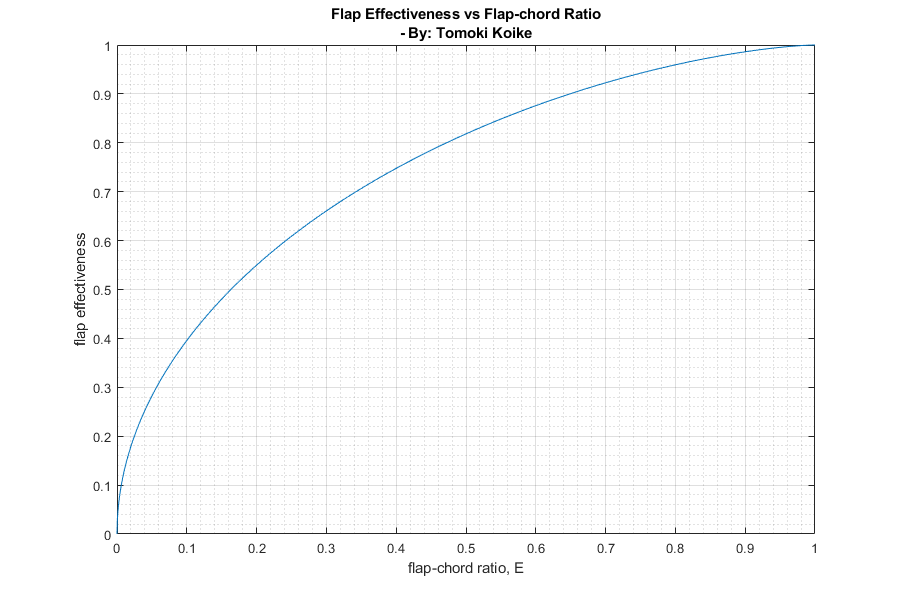

E = linspace(0,1,2^11);
alpha_zl_E = 1 + (-acos(2.*E-1) + 2*sqrt(E.*(1-E)))/pi;

% Plotting 
fig3 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(E, alpha_zl_E)
xlabel('flap-chord ratio, E')
ylabel('flap effectiveness')
title({'Flap Effectiveness vs Flap-chord Ratio', ...
    '- By: Tomoki Koike'})
grid on 
grid minor 
box on 
saveas(fig3, 'flap_effectiveness.png')

## <ii>

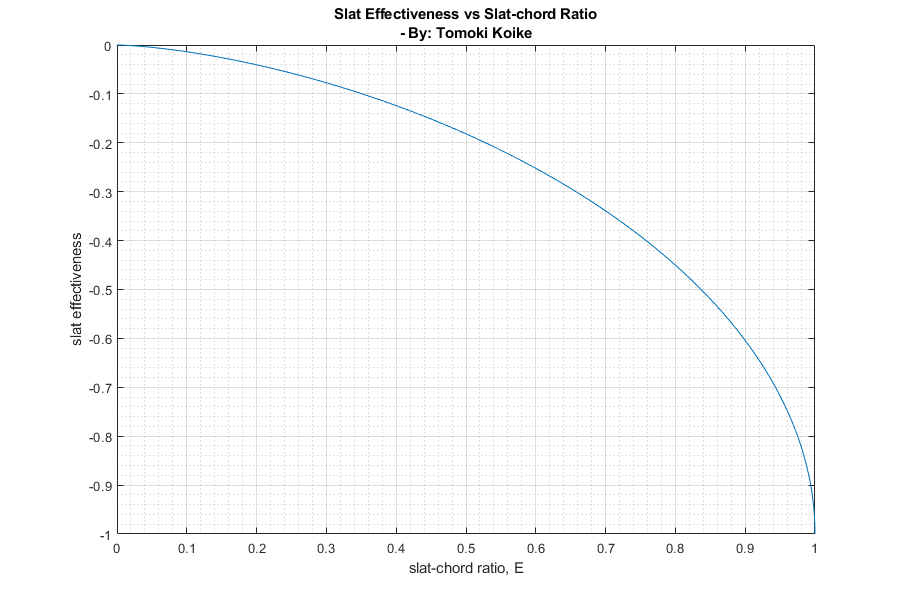

F = linspace(0,1,2^11);
alpha_zl_F = (-acos(1-2.*F) + 2*sqrt(F.*(1-F)))/pi;

% Plotting 
fig3 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(F, alpha_zl_F)
xlabel('slat-chord ratio, E')
ylabel('slat effectiveness')
title({'Slat Effectiveness vs Slat-chord Ratio', ...
    '- By: Tomoki Koike'})
grid on 
grid minor 
box on 
saveas(fig3, 'slat_effectiveness.png')

## <iii>

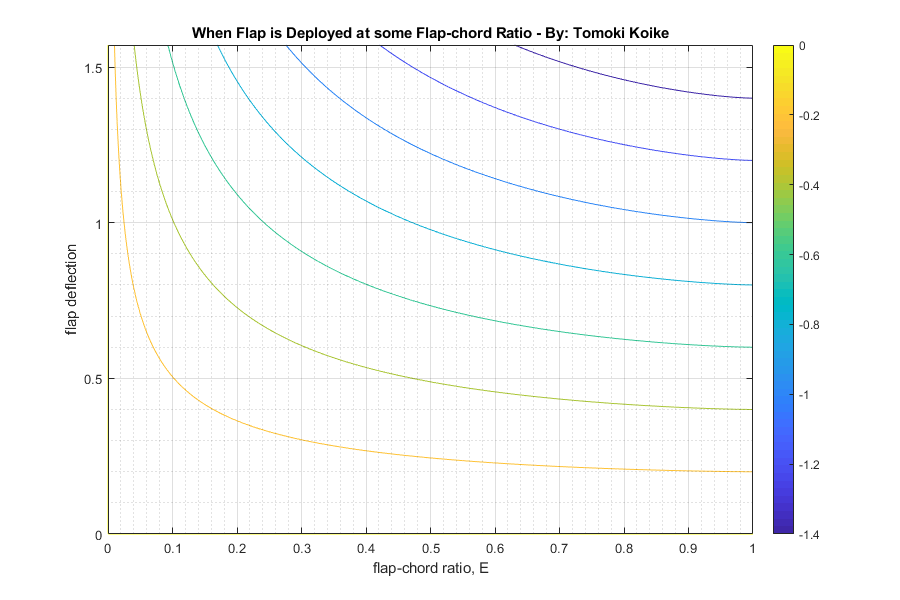

eta = linspace(0,pi/2,2^8);
[X1, Y1] = meshgrid(E, eta);
alpha_zl_E = -Y1.*(1 + (-acos(2.*X1-1) + 2*sqrt(X1.*(1-X1)))/pi);
fig4 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
contour(X1,Y1, alpha_zl_E);
xlabel('flap-chord ratio, E')
ylabel('flap deflection')
title('When Flap is Deployed at some Flap-chord Ratio - By: Tomoki Koike')
colorbar
grid on
grid minor
box on
saveas(fig4, 'flap_deployed.png')

## <iv>

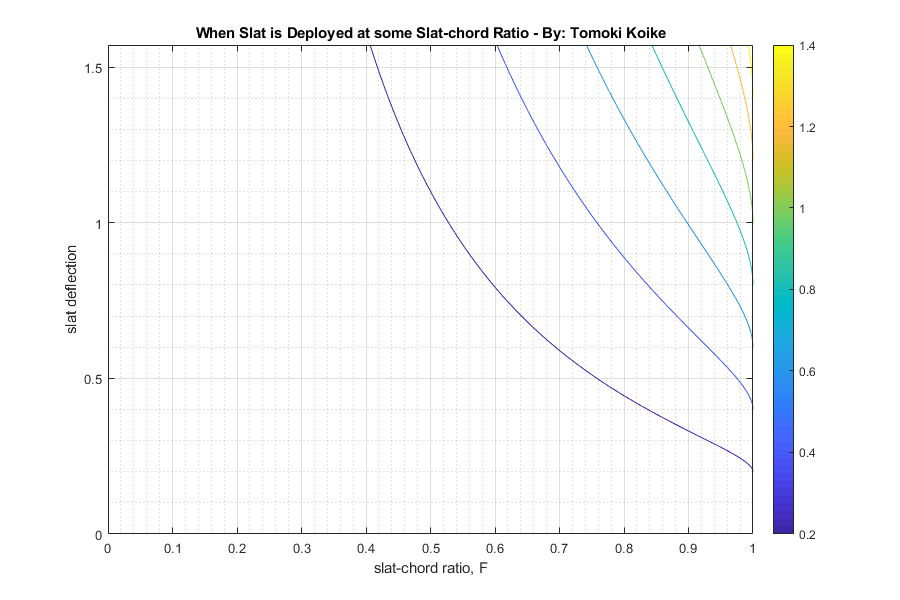

delta = linspace(0,pi/2,2^8);
[X2, Y2] = meshgrid(F, delta);
alpha_zl_F = -Y2.*(-acos(1-2.*X2) + 2*sqrt(X2.*(1-X2)))/pi;
fig4 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
contour(X2,Y2, alpha_zl_F);
xlabel('slat-chord ratio, F')
ylabel('slat deflection')
title('When Slat is Deployed at some Slat-chord Ratio - By: Tomoki Koike')
colorbar
grid on
grid minor
box on
saveas(fig4, 'slat_deployed.png')